%% 
% Parameter selection

Xtr=Ztr; Ytr=Gtr; Ytr(Ytr==0)=-1; Ytr(Ytr==1)=1; 
Xts=Zts; Yts=Gts; Yts(Yts==0) = -1; Yts(Yts==1) = 1;
[n,d]=size(Xtr);
kernel='gaussian';
kerpar=3.4 ;

K=diag(Ytr)*KernelMatrix(Xtr, Xtr, kernel, kerpar)*diag(Ytr);   
Kts=KernelMatrix(Xts, Xtr, kernel, kerpar); Ats=Kts*diag(Ytr);
%A= diag(Ytr)*K*diag(Ytr);
L=max(eig(K)) ; %mu=min(abs(eig(A)));


%% Algorithms
u0=randn(n,1); u0=u0/100; gamma=1.1/L;  T=1000; lambda0=1;    % w0 : Start. point, gamma : steps size, lambda : reg parameter

[uu1,M1,H1ts,t1]=FBdualHingeKernel(u0,Ats,K,1.1*gamma,lambda0,T,Yts);    %FB on the dual

alpha1=3 ;
[uu2,M2,H2ts,t2]=iFBdualHingeKernel(u0,Ats,K,gamma,alpha1,lambda0,T,Yts);   %i-FB on the dual with alpha 


[uvs,Mvs,Hvsts,timevs]=GDexpvarstepKernel(u0,Ats,K,1,T,Yts) ;

theta=1 ;

%[uPD,MPD,HPDts]=GDexpPrimalDual(u0,Ats,K,theta,T,Yts) ;

[uiPD,MiPD,HiPDts]=iGDexpPrimalDual(u0,Ats,K,theta,T,Yts) ;


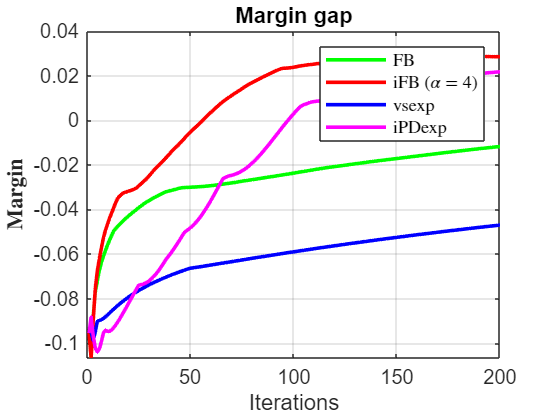


%%
figure(1)
plot(M1,'g','LineWidth',1.8) ; hold on;
plot(M2,'r','LineWidth',1.8);
plot(Mvs,'b','LineWidth',1.8);
%plot(MPD,'b','LineWidth',1.4);
plot(MiPD,'m','LineWidth',1.8);
title('Margin gap') 
xlabel('Iterations')
ylabel('$$ \textbf{Margin}$$','Interpreter','Latex')
legend('FB','iFB $(\alpha=4)$','vsexp','iPDexp','Interpreter','Latex')
grid on

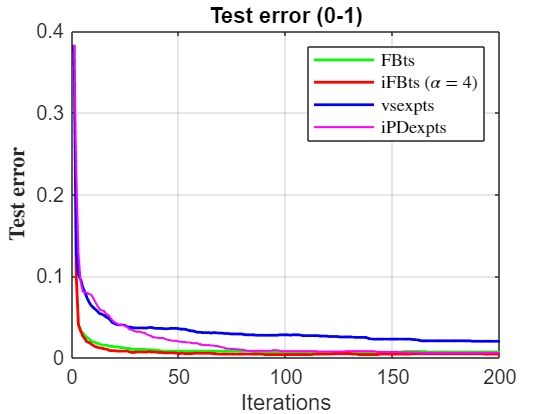


figure(2)
plot(H1ts,'g','LineWidth',1.4) ; hold on;
%plot(H1tr,'g--','LineWidth',1)
plot(H2ts,'r','LineWidth',1.4)
%plot(H2tr,'r--','LineWidth',1)
plot(Hvsts,'b','LineWidth',1.4)
%plot(Hvstr,'y--','LineWidth',1.3)
%plot(HPDts,'b','LineWidth',1)
%plot(HPDtr,'b--','LineWidth',1)
plot(HiPDts,'m','LineWidth',1)
%plot(HiPDtr,'m--','LineWidth',1)
title('Test error (0-1)') 
xlabel('Iterations')
ylabel('\textbf{Test error}','Interpreter','Latex')
legend('FBts','iFBts $(\alpha=4)$','vsexpts','iPDexpts','Interpreter','Latex')
grid on